AR = 10.69;
ZeroLiftAngle = -3;
TaperRatio = 0.4;
b = 118/2

b = 59

AoA = 0

AoA = 0

Cr = 20.5

Cr = 20.5000

LiftCurveSlope = 2*pi

LiftCurveSlope = 6.2832


eval = 100

eval = 100

    
    
interval = 90/(eval+1)

interval = 0.8911


angles = zeros(1, eval+1)

angles =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


angles(1) = 90

angles =     90     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for i = 1:eval
    
    angles(i+1) = 90-i*interval;
    
end

Chord = zeros(1,eval+1)

Chord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for i = 1:eval
    Chord(1,i) = Cr*((TaperRatio-1)*cosd(angles(i))+1);           %Fills matrix of chord values at evaluated phi locations.
end

mu = zeros(1,eval+1);
for i = 1:length(Chord)
    mu(1,i) = (Chord(1,i)*LiftCurveSlope)/(4*b);                  %Fills matrix of mu values using matrix of chord values.
end

Right_Coefficients = zeros(eval+1,eval+1);                                      %Initializes matrices to hold the coefficients on right and left side of lifting line equation.
Left_Coefficients = zeros(1,eval+1);

for i = 1:eval+1                                                           %Fills left and right coefficient matrices using lifting line equation.
    for j = 1:eval+1
        Right_Coefficients(i,j) = sind((j*2-1)*angles(1,i))*((j*2-1)*mu(1,i)+sind(angles(1,i)));
    end
    Left_Coefficients(1,i) = mu(1,i)*(AoA - ZeroLiftAngle)*sind(angles(1,i));
end

A_Values = Right_Coefficients\Left_Coefficients';

delta = 0;

for x=1:eval
    
    delta = delta + (A_Values(x+1)/A_Values(1))^2;
    
end

e = 1/(1+delta)

e = 0.9990

    
phi = zeros(1,91)

phi =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



ClCL = zeros(1,length(phi))

ClCL =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for j = 1:91
    
    phi = j
    
    SumOfSines=0
    
    for i = 1:eval+1
        
        SumOfSines = SumOfSines + A_Values(i)*sind((2*i-1)*phi);  
        
    end
    
    ClCL(j) = 2*(1+TaperRatio)/(pi*A_Values(1))*1/((TaperRatio-1)*cosd(phi)+1)*SumOfSines;
  
end

phi = 1

SumOfSines = 0

phi = 2

SumOfSines = 0

phi = 3

SumOfSines = 0

phi = 4

SumOfSines = 0

phi = 5

SumOfSines = 0

phi = 6

SumOfSines = 0

phi = 7

SumOfSines = 0

phi = 8

SumOfSines = 0

phi = 9

SumOfSines = 0

phi = 10

SumOfSines = 0

phi = 11

SumOfSines = 0

phi = 12

SumOfSines = 0

phi = 13

SumOfSines = 0

phi = 14

SumOfSines = 0

phi = 15

SumOfSines = 0

phi = 16

SumOfSines = 0

phi = 17

SumOfSines = 0

phi = 18

SumOfSines = 0

phi = 19

SumOfSines = 0

phi = 20

SumOfSines = 0

phi = 21

SumOfSines = 0

phi = 22

SumOfSines = 0

phi = 23

SumOfSines = 0

phi = 24

SumOfSines = 0

phi = 25

SumOfSines = 0

phi = 26

SumOfSines = 0

phi = 27

SumOfSines = 0

phi = 28

SumOfSines = 0

phi = 29

SumOfSines = 0

phi = 30

SumOfSines = 0

phi = 31

SumOfSines = 0

phi = 32

SumOfSines = 0

phi = 33

SumOfSines = 0

phi = 34

SumOfSines = 0

phi = 35

SumOfSines = 0

phi = 36

SumOfSines = 0

phi = 37

SumOfSines = 0

phi = 38

SumOfSines = 0

phi = 39

SumOfSines = 0

phi = 40

SumOfSines = 0

phi = 41

SumOfSines = 0

phi = 42

SumOfSines = 0

phi = 43

SumOfSines = 0

phi = 44

SumOfSines = 0

phi = 45

SumOfSines = 0

phi = 46

SumOfSines = 0

phi = 47

SumOfSines = 0

phi = 48

SumOfSines = 0

phi = 49

SumOfSines = 0

phi = 50

SumOfSines = 0

phi = 51

SumOfSines = 0

phi = 52

SumOfSines = 0

phi = 53

SumOfSines = 0

phi = 54

SumOfSines = 0

phi = 55

SumOfSines = 0

phi = 56

SumOfSines = 0

phi = 57

SumOfSines = 0

phi = 58

SumOfSines = 0

phi = 59

SumOfSines = 0

phi = 60

SumOfSines = 0

phi = 61

SumOfSines = 0

phi = 62

SumOfSines = 0

phi = 63

SumOfSines = 0

phi = 64

SumOfSines = 0

phi = 65

SumOfSines = 0

phi = 66

SumOfSines = 0

phi = 67

SumOfSines = 0

phi = 68

SumOfSines = 0

phi = 69

SumOfSines = 0

phi = 70

SumOfSines = 0

phi = 71

SumOfSines = 0

phi = 72

SumOfSines = 0

phi = 73

SumOfSines = 0

phi = 74

SumOfSines = 0

phi = 75

SumOfSines = 0

phi = 76

SumOfSines = 0

phi = 77

SumOfSines = 0

phi = 78

SumOfSines = 0

phi = 79

SumOfSines = 0

phi = 80

SumOfSines = 0

phi = 81

SumOfSines = 0

phi = 82

SumOfSines = 0

phi = 83

SumOfSines = 0

phi = 84

SumOfSines = 0

phi = 85

SumOfSines = 0

phi = 86

SumOfSines = 0

phi = 87

SumOfSines = 0

phi = 88

SumOfSines = 0

phi = 89

SumOfSines = 0

phi = 90

SumOfSines = 0

phi = 91

SumOfSines = 0

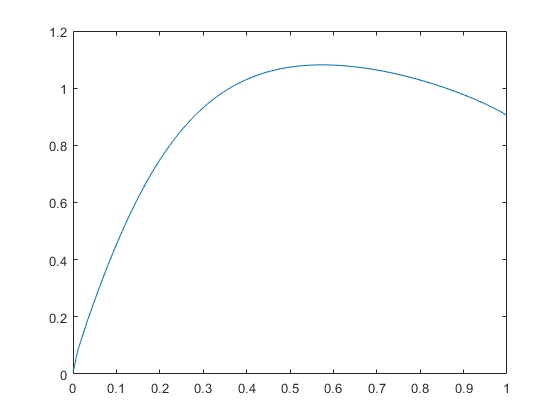


y = zeros(1,length(phi));

for k = 1:91
    
    y(k) = cosd(acosd((k-1)/90));
    
end

plot(y,ClCL)



% plot(TaperRatio,e)
% xlabel('Taper Ratio, {\it \Lambda}')
% ylabel('Oswalds Efficiency Factor, {\it e}')
% grid on


 